## Tremolo

y(n)=LFO(n)*x(n)

Low-Frequency Oscilator

## Vibrato

trojuhelnikova nebo 

**nahodna modulace **- nahodny sum, ktery projde low passem (nizko)

randn butterworth

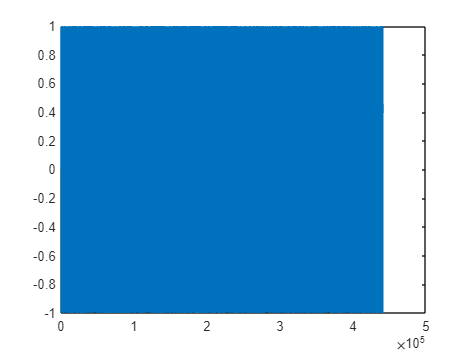

clc; clear all; close all;
[x, x_fs] = audioread("acoustic guitar.wav");
x = x(:, 1);
load("kytara1.mat")
x = a;
x_fs = 44100;

LFO = unifrnd(-1, 1, size(x, 1), 1);
plot(LFO)

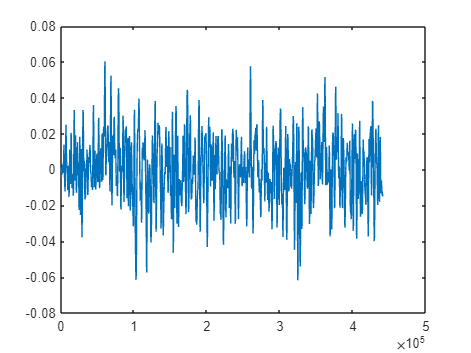

% load("LPFilter.mat")
[b, a] = butter(4, 20 / (x_fs/2), 'low');

LFO = filter(b, a, LFO);
plot(LFO)

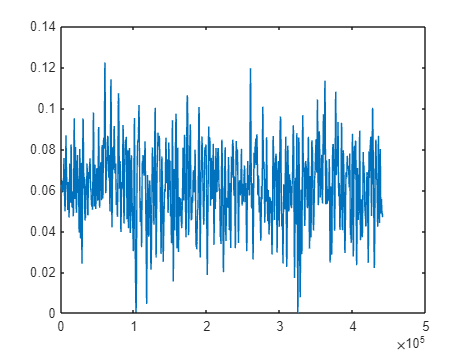

plot(LFO + abs(min(LFO)))

LFO = round((LFO + abs(min(LFO)))*x_fs/100)

LFO =     27
    27
    27
    27
    27
    27
    27
    27
    27
    27


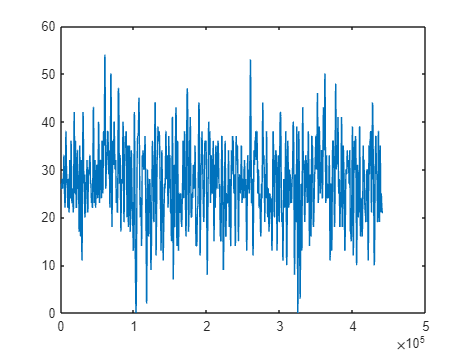

plot(LFO)


y = zeros(size(x))

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


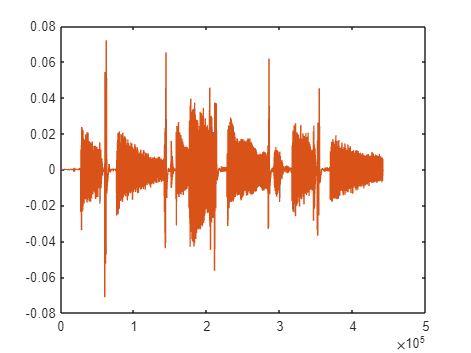

for i = 1:size(x, 1)
    index = min(max(1, i - LFO(i)), size(x, 1));
    y(i) = x(index);
end
plot(y)
hold on
plot(x)

soundsc(y, x_fs)